# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 2-c. 상태변수 모델의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 상태변수 모델의 움직임 해석

이번 topic에서는 상태변수 모델로 표현된 시스템의 상태변수 $x^d(k)$가 어떻게 움직이는 지를 해석해보는 시간을 가져보겠습니다.

이를 위해 지난 [MATLAB/Simulink 2-b](matlab:open('..\2-b\main.mlx')) 예제와 동일한 아래의 차분 방정식(difference equation)으로 표현된 이산 시간 시스템을 생각하겠습니다.


$$y^d(k+2)-1.7y^d(k+1)+0.72y^d(k)=u^d(k)$$


지난 예제에서와 같은 방법으로 상태변수 $x^d(k)$를 아래와 같이 정의하면, 


$$x^d(k) = \left[\matrix{ x_1^d(k) \cr x_2^d(k) }\right] :=\left[\matrix{ y^d(k) \cr y^d(k+1) }\right] \in \mathbb{R}^2$$


위의 이산 시간 시스템을 표현하는 상태변수 모델


$$x^d(k+1)=A^d x^d(k)+B^d u^d(k)$$



$$y^d(k) = C^d x^d(k) + D^d u^d(k)$$


의 $(A^d, B^d, C^d, D^d)$을 다음과 같이 얻습니다. 

Ad = [0 1; -0.72 1.7];
Bd = [0; 1];
Cd = [1 0];
Dd = 0;

이제 잠시 위의 상태변수 모델에서 입력을.$u^d(k) =0$로 합시다. 

그러면 위의 상태변수 모델은 입력항이 없는 다음의 차분 방정식에 의해 구동됩니다.


$$x^d(k+1)=A^d x^d(k)$$


아래에서는 다양한 초기값에 대하여 위의 상태변수 모델의 해인 $x^d(k)$를 수치적으로 얻고, 이를 $x_1^d$-$x_2^d$ 평면 상에서 그려서 거동(behavior)를 이해해보도록 하겠습니다.

미리 제작해놓은 아래의 Simulink 파일을 열어봅시다. 

open('sim_topic1.slx')

여기서는 상태변수 $x^d(k)$ 전체를 얻기 위해, Simulik Discrete State-Space 블록의 "C", "D"를 각각 단위 행렬 $I$와 영행렬 $0$으로 설정하였습니다. 

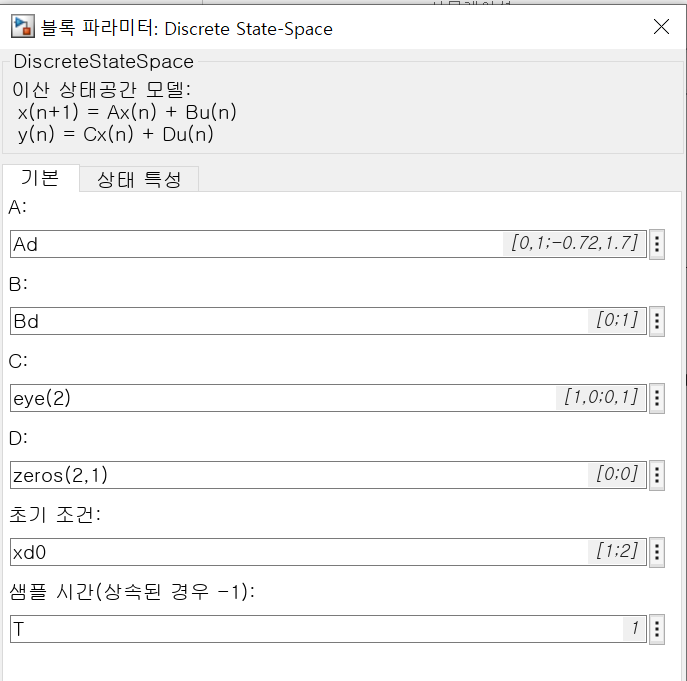

이제 4개의 서로 다른 초기값 $x^d(0)$들에 대하여 3번의 시뮬레이션을 for 문을 이용하여 구동하고, 이를 하나의 그래프로 그려보면 다음과 같습니다. 

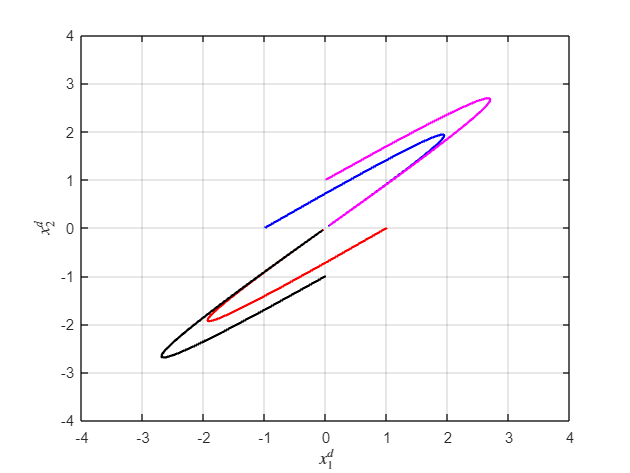

T = 1;
N = 50;

listInitialCondition = {[1; 0], [-1; 0], [0; -1], [0; 1]};
listColor = {'r','b','k','m'};

figure();
for idx = 1:length(listInitialCondition)

    xd0 = listInitialCondition{idx};
    sim('sim_topic1.slx');
    simout = ans;
    time_sim1{idx} = simout.time_sim;
    state_sim1{idx} = simout.state_sim;
    x1_sim1{idx} = simout.state_sim(:,1);
    x2_sim1{idx} = simout.state_sim(:,2);
    
    plot(x1_sim1{idx}(:,1),x2_sim1{idx}(:,1),listColor{idx},'LineWidth',1.5);
    xlim([-4 4]);
    xlabel('$x_1^d$','Interpreter','latex');
    ylim([-4 4]);
    ylabel('$x_2^d$','Interpreter','latex');
    grid on;
    hold on;
end

위의 그래프를 통해, 각기 다른 초기값을 가지더라도 상태변수 $x^d(k)$는 모두 원점으로 수렴하는 현상을 확인할 수 있습니다. 

### Topic 2 : 상태변수 모델의 유사 변환

Topic 2에서는 $2\times 2$ 행렬 $P$를 이용하여 정의된 다음의 유사 변환(similarity transformation)

$\overline{x}^d := P^{-1} x^d \in \mathbb{R}^2$ 혹은 $P\overline{x}^d = x^d$

을 통해, Topic 1의 상태변수 모델


$$x^d(k+1)=A^d x^d(k)+B^d u^d(k)$$



$$y^d(k) = C^d x^d(k) + D^d u^d(k)$$


을 가지는 시스템을 새로운 상태변수 $\overline{x}^d(k)$로 표현해보고 그 거동을 살펴보고자 합니다. 

$2\times 2$ 행렬 $P$이 역행렬이 존재하기만 하면 항상 유사 변환에 활용될 수 있지만, 여기서는 특별히 $A^d$ 행렬의 고유벡터(eigenvector)들로 구성된 특별한 형태의 $P$를 생각해보겠습니다. 

이를 위해 ${\mathtt{eig}}$ 함수를 이용하여 $A^d$ 행렬의 고유값(eigenvalue)과 고유벡터를 각각 eigVal과 eigVec라는 이름으로 저장합시다.

[Vd,diagMat] = eig(Ad);
eigVal1 = diagMat(1,1); 
eigVec1 = Vd(:,1);
eigVal2 = diagMat(2,2);
eigVec2 = Vd(:,2);

여기서 구한 고유벡터들을 열 벡터로 가지는 다음의  $2\times 2$ 행렬 $P$를 생각합시다.

P = [eigVec1 eigVec2];

위의 행렬 $P$를 이용하면 동일한 시스템을 표현하는 또 다른 상태변수 모델을 얻을 수 있습니다. 


$$\overline{x}^d(k+1)=\overline{A}^d \overline{x}^d(k)+\overline{B}^d \overline{u}^d(k)$$



$$\overline{y}^d(k) = \overline{C}^d \overline{x}^d(k) + \overline{D}^d \overline{u}^d(k)$$


여기서 새로운 상태변수 모델을 구성하는 행렬들은


$$\overline{A}^d = P^{-1} A^d P,\quad \overline{B}^d = P^{-1} B^d ,\quad \overline{C}^d = C^d P,\quad \overline{D}^d = D$$


로 정의되며, 아래와 같이 계산됩니다.

barAd = inv(P) * Ad * P;
barBd = inv(P) * Bd;
barCd = Cd * P;
barDd = Dd;

여기서 $\overline{A}^d$는 $P$를 적절히 선정한 결과로 대각화된 행렬임을 유의합시다. 

이제 위와 동일하게 입력을 $0$으로 하였을 때의 상태변수 모델을 생각해봅시다. 


$$\overline{x}^d(k+1)=\overline{A}^d \overline{x}^d(k) = \left[\matrix{0.8 & 0 \cr 0 & 0.9}\right] \overline{x}^d(k)$$


Simulink를 통해 얻은 기존 상태변수 $x^d(k)$의 궤적을 이용하면, 위의 새로운 상태변수 모델의 상태변수인 $\overline{x}^d(k)$를 다음의 방식으로 얻을 수 있습니다.

T = 1;
N = 50;

for idx = 1:length(listInitialCondition)
    barState_sim1{idx} = zeros(N+1,2);
    for time = 0:N
        barState_sim1{idx}(time+1,:) = inv(P) * state_sim1{idx}(time+1,:)';
        barState_sim1{idx}(time+1,:) = barState_sim1{idx}(time+1,:)';
    end
end

이렇게 얻은 새로운 상태변수 $\overline{x}_1^d(k)$, $\overline{x}_2^d(k)$들은, 생성되는 식이 $\overline{x}_{i}^d(k+1)=\lambda_i \overline{x}_i^d(k)$의 형태를 가지기 때문에 시간이 지남에 따라 그 크기가 항상 단조 감소하거나 단조 증가하는 경향을 보입니다. 

이는 아래의 그래프를 통해서도 확인할 수 있습니다.

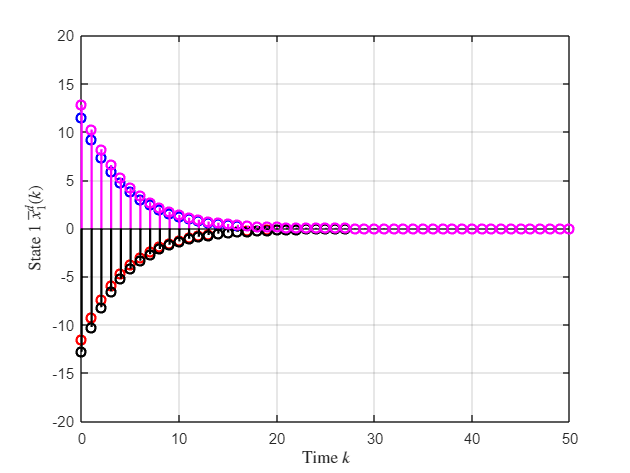

figure();
for idx = 1:length(listInitialCondition)
    barx1_sim1{idx} = barState_sim1{idx}(:,1);
    barx2_sim1{idx} = barState_sim1{idx}(:,2);
    
    stem(time_sim1{idx},barx1_sim1{idx}(:,1),listColor{idx},'LineWidth',1.5);
    xlim([0 N]);
    ylim([-20 20]);
    grid on;
    hold on;
    xlabel('Time $k$','Interpreter','latex');
    ylabel('State 1 $\overline{x}_1^d(k)$','Interpreter','latex');
end

한편 위에서 계산한 $\overline{x}^d(k)$를 새로운 평면인 $\overline{x}_1^d$-$\overline{x}_2^d$ 평면 상에서 그려보면 앞선 그래프와는 전혀 달라보이는 개형의 그래프를 얻습니다. 

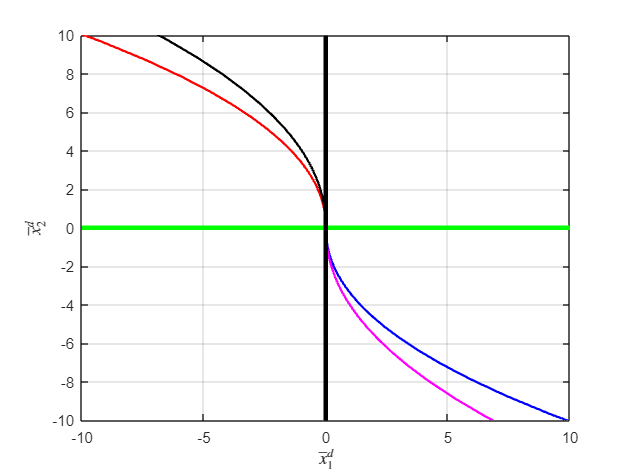

figure();
for idx = 1:length(listInitialCondition)   
    plot(barState_sim1{idx}(:,1),barState_sim1{idx}(:,2),listColor{idx},'LineWidth',1.5);
    xlim([-10 10]);
    xlabel('$\overline{x}_1^d$','Interpreter','latex');
    ylim([-10 10]);
    ylabel('$\overline{x}_2^d$','Interpreter','latex');
    grid on;
    hold on;
end
line([-10 10], [0 0]*eigVec1(2),'color','green','Linewidth',3);
hold on;
line([0 0], [-10 10],'color','black','Linewidth',3);

마지막으로 $P\overline{x}^d = x^d$ 형태의 유사 변환에서 $\overline{x}_i^d$ 값이 가지는 의미를 조금 더 고민해봅시다. 

고유벡터 $v_1$, $v_2$를 이용하여 정의된 행렬 $P=[v_1~v_2]$의 구조를 고민해볼 때, 기존 상태변수인 $x^d(k)$는 고유벡터들의 선형 조합으로 다음과 같이 표현될 수 있습니다. 

 
$$x^d = P \overline{x}^d = \overline{x}^d_1 v_1 + \overline{x}_2^d v_2$$


위의 식을 통해  $\overline{x}_i^d$는 $x^d(k)$를 표현하는 선형 조합의 가중치(weight)로써 동작함을 알 수 있습니다. 

위의 그래프에서는 $\overline{x}_1^d$의 값이 $\overline{x}_2^d$의 값에 비해 상대적으로 빨리 $0$으로 수렴하는데, 이를 통해 $x^d$는 정상상태에서 두 번째 고유벡터인 $v_2$와 매우 유사한 방향성을 가지리라는 것을 짐작할 수 있습니다. 실제로 아래 그래프에서 $x^d(k)$의 궤적에 해당하는 파란색, 핑크색 실선들은 모두 ${\rm Span}\{ v_2 \}$에 해당하는 검은색 실선을 따라서 원점으로 수렴해나감을 확인할 수 있습니다.

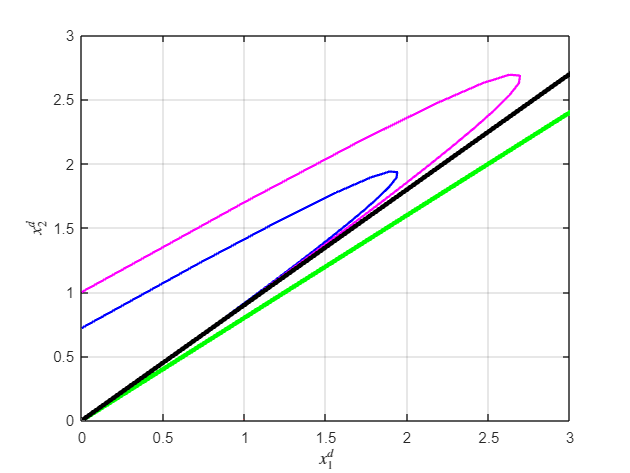

figure();
for idx = 1:length(listInitialCondition)

    xd0 = listInitialCondition{idx};
    sim('sim_topic1.slx');
    simout = ans;
    time_sim1{idx} = simout.time_sim;
    state_sim1{idx} = simout.state_sim;
    x1_sim1{idx} = simout.state_sim(:,1);
    x2_sim1{idx} = simout.state_sim(:,2);
    
    plot(x1_sim1{idx}(:,1),x2_sim1{idx}(:,1),listColor{idx},'LineWidth',1.5);
    xlim([0 3]);
    xlabel('$x_1^d$','Interpreter','latex');
    ylim([0 3]);
    ylabel('$x_2^d$','Interpreter','latex');
    grid on;
    hold on;
end
line([-10 10]*eigVec1(1), [-10 10]*eigVec1(2),'color','green','Linewidth',3);
hold on;
line([-10 10]*eigVec2(1), [-10 10]*eigVec2(2),'color','black','Linewidth',3);

한편 위에서 구한 2개의 서로 달라보이는 상태변수 모델은, ${\mathtt{ss}}$ 모델 객체의 형태로 아래와 같이 각각 정의가 가능합니다.

sys1 = ss(Ad,Bd,Cd,Dd,T);
sys2 = ss(barAd,barBd,barCd,barDd,T);

이들은 당연하게도 같은 시스템을 표현하는데, 아래 명령어를 통해 위의 두 상태변수 모델들이 동일한 전달함수를 가짐을 쉽게 확인할 수 있습니다.

tf(sys1)

ans =
 
          1
  ------------------
  z^2 - 1.7 z + 0.72
 
샘플 시간: 1 seconds
이산시간 전달 함수입니다.
모델 속성


tf(sys2)

ans =
 
          1
  ------------------
  z^2 - 1.7 z + 0.72
 
샘플 시간: 1 seconds
이산시간 전달 함수입니다.
모델 속성


### Topic 3 : 상태변수 모델의 일반해

Topic 3에서는 상태변수 모델의 일반해에 대해 이해해보는 시뮬레이션을 수행하겠습니다. 

기본적으로 다음의 상태변수 모델


$$x^d(k+1)=A^d x^d(k)+B^d u^d(k)$$



$$y^d(k) = C^d x^d(k) + D^d u^d(k)$$


의 해(solution)인 $y^d(k)$는 다음과 같이 두 신호의 합으로 표현 가능합니다. 


$$y^d(k)=y_{\rm ZI}^d(k) + y_{\rm ZS}^d(k)$$


여기서 $y_{\rm ZI}^d(k) = C^d (A^d)^k x^d(0)$은 초기값에 대한 영향을 대변하는 zero-input response를, $y_{\rm ZS}^d(k) = \sum_{j=0}^{k}(A^d)^{k-j}B^d u(j)$는 입력에 대한 영향을 대변하는 zero-state response를 의미합니다. 

아래 예제에서는 위에서 두 response의 합으로 계산한 결과물과 실제 output만을 다른 방식으로 얻어낸 결과를 비교해보도록 하겠습니다.

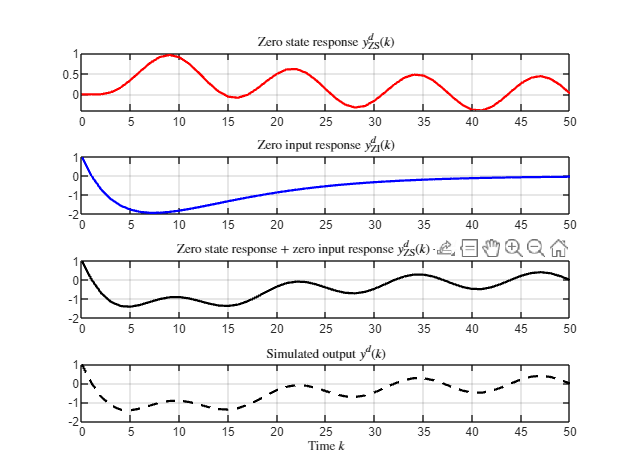

open("sim_topic3.slx");

xd0 = [1; 0];
sim('sim_topic3.slx');
simout = ans;
time_sim2 = simout.time_sim;
zeroStateResp_sim2 = simout.zeroStateResp_sim;
zeroInputResp_sim2 = simout.zeroInputResp_sim;
output_sim2 = simout.output_sim;

figure();
subplot(4,1,1);
    plot(time_sim2,zeroStateResp_sim2,'r','LineWidth',1.5);
    title('Zero state response $y_{\rm ZS}^d(k)$','Interpreter','latex');
    grid on;
subplot(4,1,2);
    plot(time_sim2,zeroInputResp_sim2,'b','LineWidth',1.5);
    title('Zero input response $y_{\rm ZI}^d(k)$','Interpreter','latex');
    grid on;
subplot(4,1,3);
    plot(time_sim2,zeroStateResp_sim2 + zeroInputResp_sim2,'k','LineWidth',1.5);
    title('Zero state response + zero input response $y_{\rm ZS}^d(k)+y_{\rm ZI}^d(k)$','Interpreter','latex');
    grid on;
subplot(4,1,4);
    plot(time_sim2,output_sim2,'--k','LineWidth',1.5);
    title('Simulated output $y^d(k)$','Interpreter','latex');
    xlabel('Time $k$','Interpreter','latex');
    grid on;